# 3-D Point Cloud Registration and Stitching

This example shows how to combine multiple point clouds to reconstruct a 3-D scene using Iterative Closest Point (ICP) algorithm. It then shows how to leverage color information available in the point clouds to improve the accuracy of the scene.

## Overview

This example stitches together a collection of point clouds that was captured with Kinect to construct a larger 3-D view of the scene. The example applies ICP to two successive point clouds. This type of reconstruction can be used to develop 3-D models of objects or build 3-D world maps for simultaneous localization and mapping (SLAM).

## Load Point Cloud Data

The point cloud data is available as a cell array of [`pointCloud`](docid:vision_ref#buphqma-1) objects. Download the data to a temporary directory.

dataURL = "https://www.mathworks.com/supportfiles/vision/data/livingRoom.mat";
pointCloudFolder = fullfile(tempdir,"pointCloudDataRegistrationAndStitching");
pointCloudData = fullfile(pointCloudFolder,"livingRoom.mat");

% Download the point cloud data.
if ~exist(pointCloudData,"file")
    if ~exist(pointCloudFolder,"dir")
        mkdir(pointCloudFolder);
    end
    disp("Downloading point cloud data (5.5 MB)...");
    websave(pointCloudData,dataURL);
end
% Load the point cloud data.
load(pointCloudData);

% Extract two consecutive point clouds to use the first point cloud as
% reference.
ptCloudRef = livingRoomData{1};
ptCloudCurrent = livingRoomData{2};

## Register Two Point Clouds

The quality of registration depends on data noise and initial settings of the ICP algorithm. You can apply preprocessing steps to filter the noise or set initial property values appropriate for your data. Here, preprocess the data by downsampling with a grid nearest filter and set the size of the grid to 0.1 m. The grid filter divides the point cloud space into voxels. For each voxel, it selects the nearest point to the centroid of the voxel.

gridSize = 0.1;
fixed = pcdownsample(ptCloudRef,gridNearest=gridSize);
moving = pcdownsample(ptCloudCurrent,gridNearest=gridSize);

Note that the downsampling step does not only speed up the registration, but can also improve the accuracy.

To align the two point clouds, use the point-to-plane ICP algorithm to estimate the 3-D rigid transformation on the downsampled data. Use the first point cloud as the reference and then apply the estimated transformation to the original second point cloud. Merge the scene point cloud with the aligned point cloud to process the overlapped points.

Begin by finding the rigid transformation to align the second point cloud with the first point cloud. Use it to transform the second point cloud to the reference coordinate system defined by the first point cloud.

tform = pcregistericp(moving,fixed,Metric="pointToPlane");
ptCloudAligned = pctransform(ptCloudCurrent,tform);

You can now create the world scene with the registered data. The overlapped region is filtered using a 0.015 m box grid filter. Increase the merge size to reduce the storage requirement of the resulting scene point cloud, and decrease the merge size to increase the scene resolution.

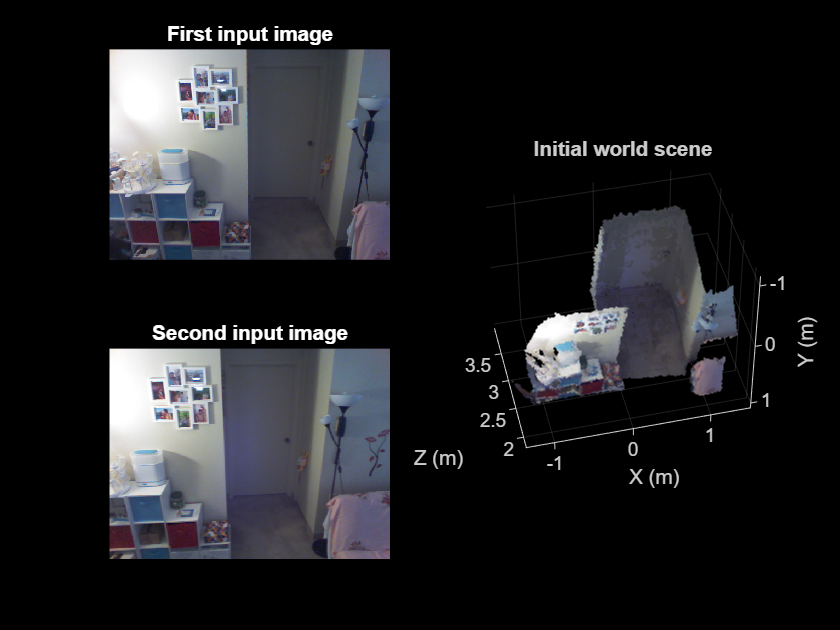

mergeSize = 0.015;
ptCloudScene1 = pcmerge(ptCloudRef,ptCloudAligned,mergeSize);

% Visualize the input images.
figure
subplot(2,2,1)
imshow(ptCloudRef.Color)
title("First input image",Color="w")

subplot(2,2,3)
imshow(ptCloudCurrent.Color)
title("Second input image",Color="w")

% Visualize the world scene.
subplot(2,2,[2,4])
pcshow(ptCloudScene1,VerticalAxis="Y",VerticalAxisDir="Down")
title("Initial world scene")
xlabel("X (m)")
ylabel("Y (m)")
zlabel("Z (m)")

## Stitch a Sequence of Point Clouds

To compose a larger 3-D scene, repeat the same procedure as above to process a sequence of point clouds. Use the first point cloud to establish the reference coordinate system. Transform each point cloud to the reference coordinate system. This transformation is a multiplication of pairwise transformations.

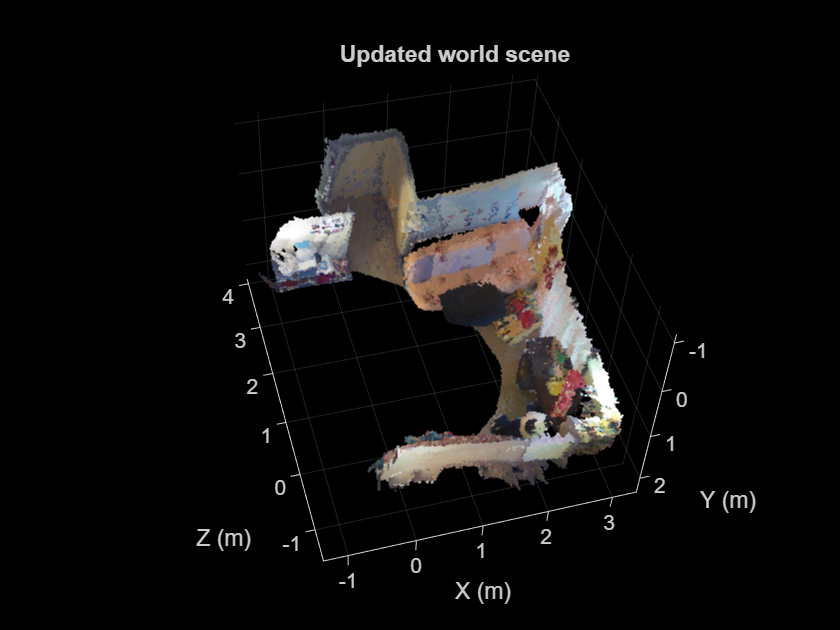

% Store the transformation object that accumulates the transformation.
accumTform = tform; 

figure
hAxes = pcshow(ptCloudScene1,VerticalAxis="Y",VerticalAxisDir="Down");
title("Updated world scene")
xlabel("X (m)")
ylabel("Y (m)")
zlabel("Z (m)")

% Set the axes property for faster rendering.
hAxes.CameraViewAngleMode = "auto";
hScatter = hAxes.Children;

for i = 3:length(livingRoomData)
    ptCloudCurrent = livingRoomData{i};
       
    % Use previous moving point cloud as reference.
    fixed = moving;
    moving = pcdownsample(ptCloudCurrent,gridNearest=gridSize);
    
    % Apply ICP registration.
    tform = pcregistericp(moving,fixed,Metric="pointToPlane");

    % Transform the current point cloud to the reference coordinate system
    % defined by the first point cloud.
    accumTform = rigidtform3d(accumTform.A * tform.A);
    ptCloudAligned = pctransform(ptCloudCurrent,accumTform);
    
    % Update the world scene.
    ptCloudScene1 = pcmerge(ptCloudScene1,ptCloudAligned,mergeSize);

    % Visualize the world scene.
    hScatter.XData = ptCloudScene1.Location(:,1);
    hScatter.YData = ptCloudScene1.Location(:,2);
    hScatter.ZData = ptCloudScene1.Location(:,3);
    hScatter.CData = ptCloudScene1.Color;
    drawnow("limitrate")
end

During the recording, the Kinect was pointing downward. Transform the scene so that the ground plane is parallel to the X-Z plane.

angle = -10;
translation = [0 0 0];
tform = rigidtform3d([angle 0 0],translation);
ptCloudScene1 = pctransform(ptCloudScene1,tform);

Change the camera angle of the plot to inspect the stitched results closer.

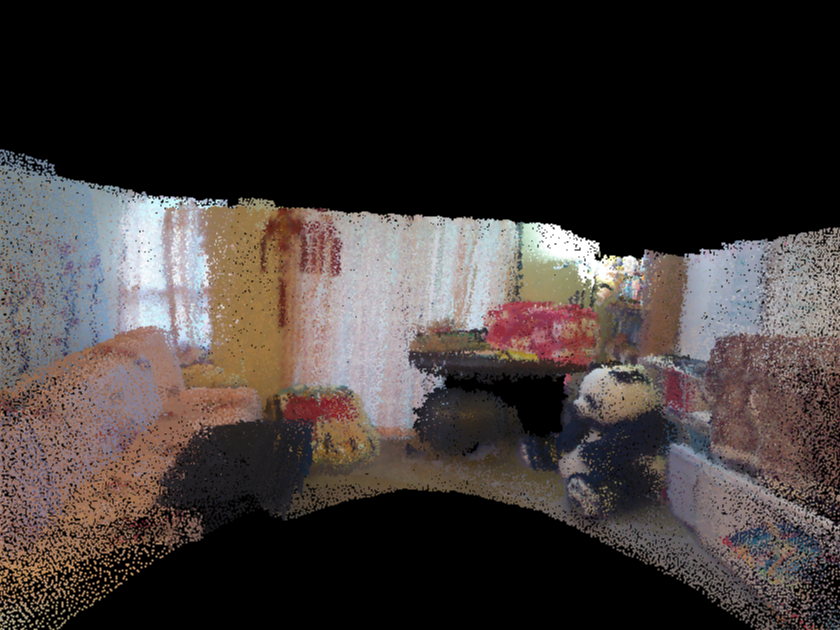

hAxes1 = pcshow(ptCloudScene1,AxesVisibility="off");
hAxes1.CameraPosition = [-0.6 0.2 0.5];
hAxes1.CameraTarget = [1.3 0.5 0.3];
hAxes1.CameraUpVector = [0.2 -0.9 -0.1];
hAxes1.CameraViewAngle = 60;

Even though the stitched scene appears to be aligned, there is some drift in parts of the scene that becomes noticeable when inspecting it closer. For example, the flowers on the desk near the panda are not aligned properly. Depending on the application, you might want to improve the accuracy of the scene even further. To improve the results, you can try using the ICP algorithm with the Metric name-value argument set to "planeToPlane". Alternatively, if your point cloud includes color information, you can use it to improve the accuracy of the 3-D scene.

## Stitch a Sequence of Point Clouds Using Color Information

The `pcregistericp` function uses the color information of the point clouds when setting the Metric name-value argument to "pointToPlaneWithColor" or "planeToPlaneWithColor". The function `helperStitchPointCloudsUsingColor` repeats the steps in the previous section with the Metric name-value argument set to "pointToPlaneWithColor".

Stitch the point cloud sequence using the color information.

ptCloudScene2 = helperStitchPointCloudsUsingColor(livingRoomData);

Visualize the updated world scene.

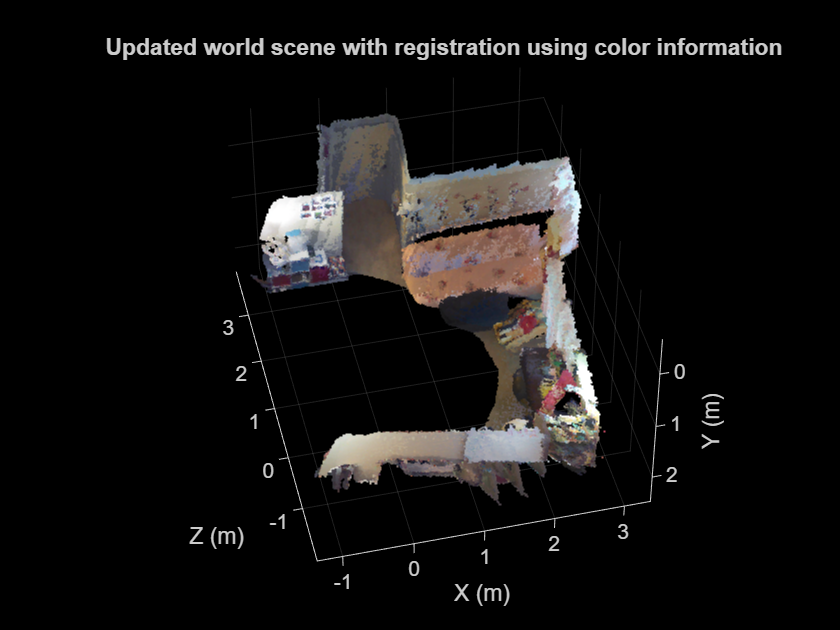

figure
pcshow(ptCloudScene2,VerticalAxis="Y",VerticalAxisDir="Down")
title("Updated world scene with registration using color information")
xlabel("X (m)")
ylabel("Y (m)")
zlabel("Z (m)")

Change the camera angle of the plot to inspect the stitched results closer.

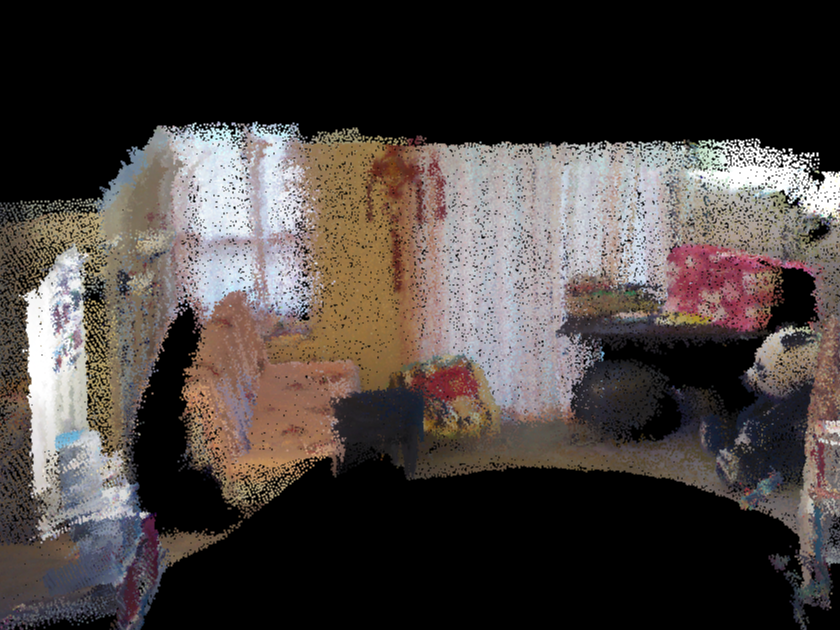

hAxes2 = pcshow(ptCloudScene2,AxesVisibility="off");
hAxes2.CameraPosition = [-12.6 -2.9 -0.9];
hAxes2.CameraTarget = [27.3 7.4 3.6];
hAxes2.CameraUpVector = [0.27 -0.93 -0.24];
hAxes2.CameraViewAngle = 11;

Leveraging the color information available with the point clouds, reduced the drift in the stitched scene. For example, the alignment of the flowers next to the panda improved in the resulting 3-D scene.

## Conclusion

This example demonstrates how to stitch multiple point clouds to reconstruct a 3-D scene using ICP point cloud registration. It also shows how to leverage the color information present in the point clouds using ICP to improve the accuracy of the reconstructed scene.

## Supporting Functions

The `helperStitchPointCloudsUsingColor` function returns the reconstructed world scene by stitching multiple point clouds using the `pcregistericp` function with the "pointToPlaneWithColor" metric.

function ptCloudScene = helperStitchPointCloudsUsingColor(livingRoomData)

% Extract the first point cloud as reference.
ptCloudRef = livingRoomData{1};

% Downsample the point cloud.
gridSize = 0.1;
moving = pcdownsample(ptCloudRef,gridNearest=gridSize);

% Set the merge size to merge each point cloud to the scene.
mergeSize = 0.015;
ptCloudScene = ptCloudRef;

% Store the transformation object that accumulates the transformation.
accumTform = rigidtform3d();

for i = 2:length(livingRoomData)
    ptCloudCurrent = livingRoomData{i};
       
    % Use previous moving point cloud as reference.
    fixed = moving;
    moving = pcdownsample(ptCloudCurrent,gridNearest=gridSize);
    
    % Apply ICP registration.
    tform = pcregistericp(moving,fixed,Metric="pointToPlaneWithColor",InlierDistance=0.1);

    % Transform the current point cloud to the reference coordinate system
    % defined by the first point cloud.
    accumTform = rigidtform3d(accumTform.A * tform.A);
    ptCloudAligned = pctransform(ptCloudCurrent,accumTform);
    
    % Update the world scene.
    ptCloudScene = pcmerge(ptCloudScene,ptCloudAligned,mergeSize);
end

% During the recording, the Kinect was pointing downward.
% Transform the scene so that the ground plane is parallel
% to the X-Z plane.
angle = -10;
translation = [0 0 0];
tform = rigidtform3d([angle 0 0],translation);
ptCloudScene = pctransform(ptCloudScene,tform);
end

*Copyright 2014-2023 The MathWorks, Inc.*